# Assignment

## The Travelling Salesperson Problem

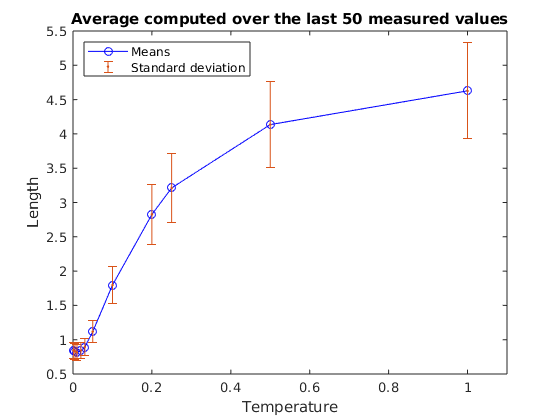

T = [1, 0.5, 0.25, 0.2, 0.1, 0.05, 0.03, 0.02, 0.01, 0.005, 0.001];
means = zeros(1, length(T));
vars = zeros(1, length(T));

nSimulations = 50;
N = 100;
maxsteps = 500;

for i = 1:length(T)
    meanSim = 0;
    varSim = 0;
    for count = 1:nSimulations
        curr_result = tsp(N, maxsteps, T(i));
        
        meanSim = meanSim + curr_result('mean');
        varSim = varSim + curr_result('var');
    end
    
    means(i) = meanSim ./ nSimulations;
    vars(i) = varSim ./ nSimulations;
end

plot(T, means, 'bo-')
hold on
errorbar(T, means, sqrt(vars), '.')
title('Average computed over the last 50 measured values')
xlim([0, T(1)+0.1])
xlabel('Temperature')
ylabel('Length')
legend('Means', 'Standard deviation', 'Location', 'northwest')
hold off

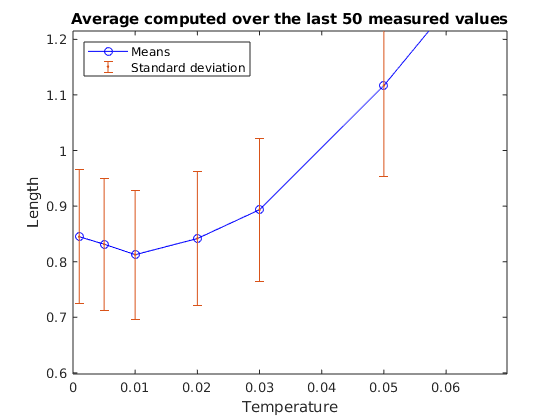


plot(T, means, 'bo-')
hold on
errorbar(T, means, sqrt(vars), '.')
title('Average computed over the last 50 measured values')
xlim([0.0000 0.0698])
ylim([0.598 1.215])
xlabel('Temperature')
ylabel('Length')
legend('Means', 'Standard deviation', 'Location', 'northwest')
hold off